# State feedback

clear all; close all; clc

## Constantes del modelo.

m = 0.1818; 
M = 0.6042;
Mt = 10;
l = 0.09; %cm 
g = 10;
J = 0.45e-3;
%JJt = J+m*l^2;
Jt = 2.744e-3;
mu = Mt*Jt-(m^2)*(l^2);

## Modelo del sistema sistema

%Variables de estado y entrada
syms x1 x2 x3 x4;       %q theta q_d theta_d
syms u;

%Ecuaciones no lineales. Modelo de Astrom & Murray 3-13.
x1d = x3;
x2d = x4;
x3d = (-m*l*sin(x2)*(x4^2)+m*g*(m*(l^2)/Jt)*sin(x2)*cos(x2)+u)/(Mt-m*(m*(l^2)/Jt)*(cos(x2))^2);
x4d = (-m*(l^2)*sin(x2)*cos(x2)*(x4^2)+Mt*g*l*sin(x2)+l*cos(x2)*u)/((Jt*Mt/m)-m*(l*cos(x2))^2);
h1 = [x1; x2];

% Vectores
x = [x1; x2; x3; x4];
f = [x1d; x2d; x3d; x4d];
h = [h1];

%Linealizacion del sistema (Jacobiano)
A = jacobian(f, x);  %df/dx
B = jacobian(f, u);  %df/du
C = jacobian(h, x);  %dh/dx
D = jacobian(h, u);  %dh/du

% Puntos de equlibrio
x1_eq = 0;
x2_eq = 0;
x3_eq = 0;
x4_eq = 0;
u_eq = 0;

Xeq = [x1_eq x2_eq x3_eq x4_eq];
delta_xeq = [0 0 0 0];
Ueq = [u_eq];

%Calculo mmatrices en pto de equlibrio
A = subs(A, {'x1','x2','x3', 'x4', 'u'}, {x1_eq, x2_eq, x3_eq, x4_eq, u_eq});
B = subs(B, {'x1','x2','x3', 'x4','u'}, {x1_eq, x2_eq, x3_eq, x4_eq, u_eq});
C = subs(C, {'x1','x2','x3', 'x4','u'}, {x1_eq, x2_eq, x3_eq, x4_eq, u_eq});
D = subs(D, {'x1','x2','x3', 'x4','u'}, {x1_eq, x2_eq, x3_eq, x4_eq, u_eq});

% Gss : Sistema linealizado en espacio de estados
A = double(A);
B = double(B);
C = double(C);
D = double(D);

## Estabilidad del sistema linealizado

Analizar la estabilidad del sistema linealizado

Gss = ss(A,B,C,D);
eig(A)

ans =          0
         0
    7.7599
   -7.7599


Funcion de transferencia del modelo linealizado

T = zpk(Gss);
stepinfo(T)

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


Controlabilidad

Cm = ctrb(A,B);
RankCm = rank(Cm)

RankCm = 4

Observabilidad

Om = obsv(A,C);
RankOm = rank(Om)

RankOm = 4

## Realimentacion de estados

Requisitos del sistema

Ts = 5;
Overshoot = 15; % (Porcentaje)

% Calculo de polos deseados
zi = -log(Overshoot/100)/sqrt(pi^2+(log(Overshoot/100))^2);
wn = 4/(Ts*zi);

s1 = -zi*wn + 1i*wn*sqrt(1-zi^2);
s2 = -zi*wn - 1i*wn*sqrt(1-zi^2);

cp = [s1 s2 -10 -10]

cp =   -0.8000 + 1.3248i  -0.8000 - 1.3248i -10.0000 + 0.0000i -10.0000 + 0.0000i


% Calcula la matriz del sistema a lazo cerrado.
K = acker(A,B,cp);
Acl = A-B*K;
eig(Acl)

ans =  -10.0000 + 0.0000i
 -10.0000 + 0.0000i
  -0.8000 + 1.3248i
  -0.8000 - 1.3248i



% Calcula la transferencia a lazo cerrado.
Gss_cl = ss(Acl,B,C,D);
T_cl = zpk(Gss_cl);

% Error permanente
ess = 1 - dcgain(T_cl)

ess =     1.0251
    1.0000


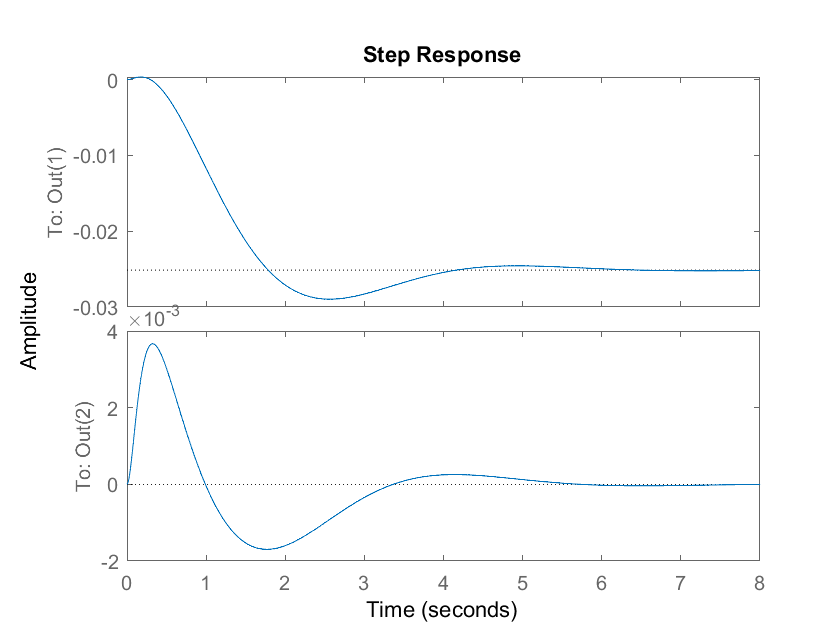

% Escalon
stepinfo(T_cl);
step(T_cl);

## Accion integral

% Matrices aumentadas
Aa = [Gss.A zeros(order(Gss),2); -Gss.C zeros(2,2)];
Ba = [Gss.B; -Gss.D];
Ca = [C zeros(2,2)];
Da = [D];

Calculo de polos

cpa = cp;
cpa(end+1) = cpa(end)*5;
cpa(end+1) = cpa(end);

Controlabilidad y observabilidad

Cm = ctrb(Aa,Ba);
RankCm = rank(Cm)

RankCm = 5


Om = obsv(Aa,Ca);
RankOm = rank(Om)

RankOm = 4

Ganancias

Ka = acker(Aa, Ba, cpa);

Error using eig
Input matrix contains NaN or Inf.

Error in acker (line 48)
pc = sort(eig(a-b*k));

K_  = Ka(1:order(Gss)); 
Ki = -Ka(end);

## Discretizacion

## Realimentación de estados REURISON

%x = [p,q,v,w]
K = 1.0e+03 * [-8.4073,3.7519,-2.2419,0.4756];